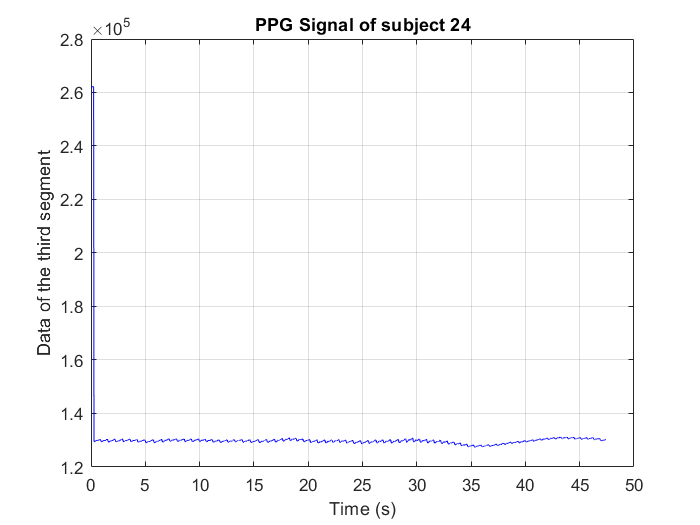

%file24_3 = fopen('C:\Users\Saba\Downloads\data\UData\24_3.txt','r');
%format = '%f';
%data24_3 = fscanf(file24_3,format);
Tab = readtable('C:\Users\Saba\Downloads\data\Raw Data\ID2-72.csv','HeaderLines',3); 
%Tab = readtable('C:\MaximLogs\Me0.csv','HeaderLines',3);
data=Tab(:,3:7);
data=table2array(data);
data(isnan(data(:,1)))=0;
PPG=data(:,1:2);
data24_3=PPG(:,1);
l=length(data24_3);
f=100; %HZ
tmax=l/f;
tmin=0;
t=tmin:tmax/(l-1):tmax;
plot(t,data24_3,'b')
%xlim([5 10])
grid on
title('PPG Signal of subject 24')
ylabel('Data of the third segment')
xlabel('Time (s)')         

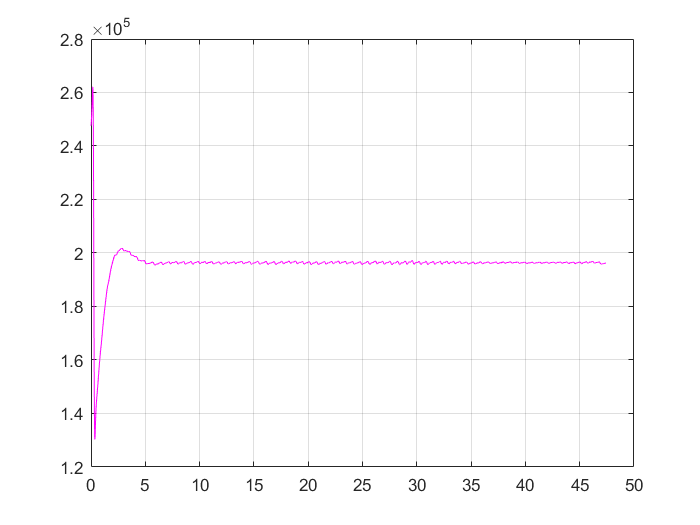

lw=0.2;
hw=5;
w1=lw/(f/2);
w2=hw/(f/2);
[b,a]=butter(2,[w1,w2]);
dd=filtfilt(b,a,data24_3);
plot(t,dd+max(data24_3)-max(dd),'m')
%xlim([5 10])
grid on

# **Range**

[pks,locs]=findpeaks(data24_3);
Pk=max(pks);
for i=1:1:length(data24_3)
    if data24_3(i)==Pk
        k=t(i);
    end
end

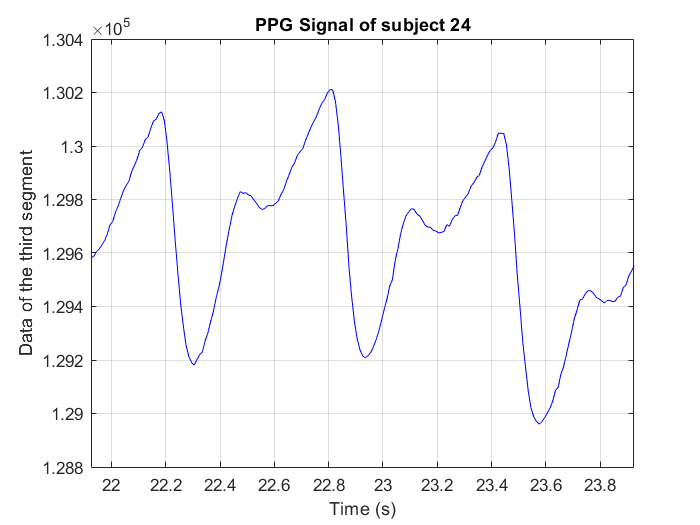

plot(t,data24_3,'b')
if k>=tmax/2
    xlim([k/2 k/2+2])
elseif k<tmax/2
    xlim([tmax/2-k tmax/2+k])
end
%xlim([5 10])
grid on
title('PPG Signal of subject 24')
ylabel('Data of the third segment')
xlabel('Time (s)')  

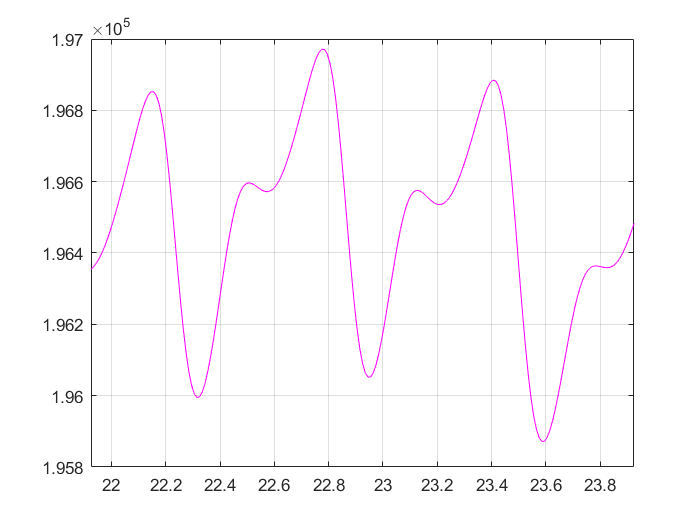

plot(t,dd+max(data24_3)-max(dd),'m')
if k>=tmax/2
    xlim([k/2 k/2+2])
elseif k<tmax/2
    xlim([tmax/2-k tmax/2+k])
end
   
%xlim([5 10])
grid on